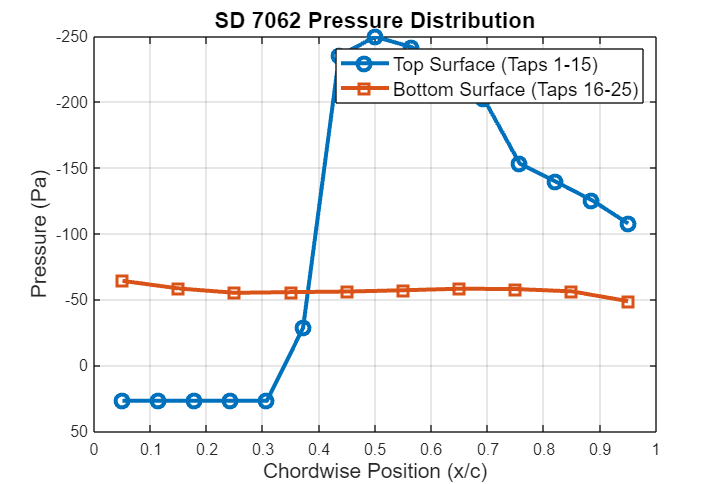

% Load all CSV files
top_1 = readmatrix('7062_top_readings_860rpm.csv');
top_2 = readmatrix('7062_860rpm_top_readings.csv');
bottom_1 = readmatrix('7062_860rpm_bottomreadings.csv');
bottom_2 = readmatrix('7062_bottom_readings_860rpm.csv');

% Extract pressure columns
top_press_1 = top_1(:, 8:22);      % 15 columns for taps 1-15
top_press_2 = top_2(:, 8:22);
bottom_press_1 = bottom_1(:, 8:17); % 10 columns for taps 16-25
bottom_press_2 = bottom_2(:, 8:17);

% Average across all measurement rows
top_avg_1 = mean(top_press_1, 1, 'omitnan');
bottom_avg_1 = mean(bottom_press_1, 1, 'omitnan');

% Define chordwise positions (x/c) for each tap
top_xc = linspace(0.95, 0.05, 15);      % TE to LE
bottom_xc = linspace(0.05, 0.95, 10);   % LE to TE

% Plot pressure distribution
figure('Position', [100, 100, 900, 600]);
plot(top_xc, top_avg_1, '-o', 'LineWidth', 2.5, 'MarkerSize', 8, ...
    'DisplayName', 'Top Surface (Taps 1-15)');
hold on;
plot(bottom_xc, bottom_avg_1, '-s', 'LineWidth', 2.5, 'MarkerSize', 8, ...
    'DisplayName', 'Bottom Surface (Taps 16-25)');

xlabel('Chordwise Position (x/c)', 'FontSize', 13);
ylabel('Pressure (Pa)', 'FontSize', 13);
title('SD 7062 Pressure Distribution', 'FontSize', 14);
legend('FontSize', 12);
grid on;
set(gca, 'YDir', 'reverse');  % Negative pressures plotted downward
xlim([0 1]);